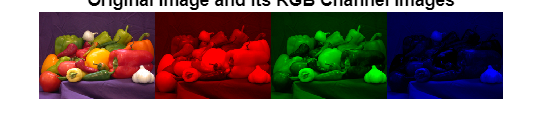

img = imread('peppers.png'); 

redChannel   = img(:,:,1);
greenChannel = img(:,:,2);
blueChannel  = img(:,:,3);

redImage   = cat(3, redChannel, zeros(size(redChannel)), zeros(size(redChannel)));
greenImage = cat(3, zeros(size(greenChannel)), greenChannel, zeros(size(greenChannel)));
blueImage  = cat(3, zeros(size(blueChannel)), zeros(size(blueChannel)), blueChannel);

figure;
montage({img, redImage, greenImage, blueImage}, 'Size', [1 4]);
title('Original Image and its RGB Channel Images');